**Graphs of the RP frecuent and infrequent **

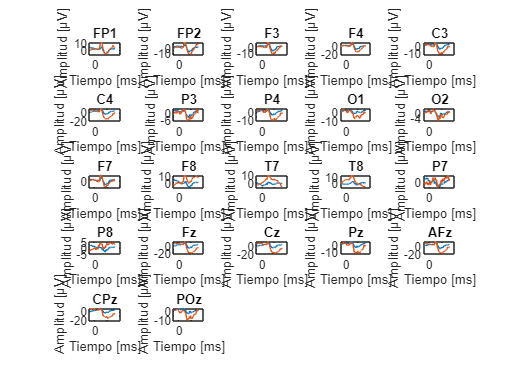

RPF= mean(ALLEEG(7).data, 3);
RPI=mean(ALLEEG(8).data, 3);

figure
for i=1:22
    subplot(5,5,i)
    plot(EEG.times,RPF(i,:))
    hold on
    plot(EEG.times,RPI(i,:))
    hold off

   title(EEG.chanlocs(i).labels);
   ylabel("Amplitud [μV]")
   xlabel("Tiempo [ms]")
   hold off

    [rxx(i,:),lags(i,:)] = xcorr(RPI(i,:),RPF(i,:),'normalized');  
  
end

**Find maximum and minmun cross correlation**

for k=1:22
    [~,maximoI(k,:)] = max(abs(rxx(k,:)));  % The I index is obtained where the maximum correlation occurs. Point at which the signals are highly similar.
    [~,minimoI(k,:)] = min(abs(rxx(k,:)));
    magnitudesM(k,1)=rxx(k,maximoI(k,1));
    magnitudesMIN(k,1)=rxx(k,minimoI(k,1));
end



indice_1=max(abs(magnitudesM)) %Find in which channel is that magnitude

indice_1 = single
0.8933

indice_2=min(abs(magnitudesMIN)) %Find in which channel is that magnitude

indice_2 = single
1.5180e-06

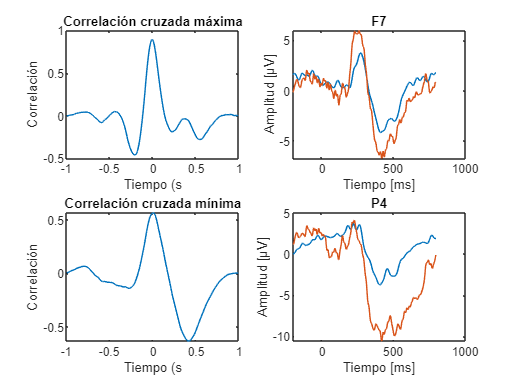


figure
subplot(2,2,1)
    plot(lags(11,:)/EEG.srate,rxx(11,:));
    ylabel('Correlation')
    xlabel('Time (s')
    title('Maximum Cross-correlation') 

 subplot(2,2,2)
  plot(EEG.times,RPF(11,:))
    hold on
    plot(EEG.times,RPI(11,:))
    hold off
  title(EEG.chanlocs(11).labels);
   ylabel("Amplitude [μV]")
   xlabel("Time [ms]")

%%MINIMOS 
subplot(2,2,3)
    plot(lags(8,:)/EEG.srate,rxx(8,:));
    ylabel('Correlation')
    xlabel('Time(s')
    title('Minimum Cross-correlation') 

 subplot(2,2,4)
  plot(EEG.times,RPF(8,:))
    hold on
    plot(EEG.times,RPI(8,:))
    hold off
  title(EEG.chanlocs(8).labels);
   ylabel("Amplitude [μV]")
   xlabel("Time [ms]")

**This code it gives you the cross correlations of each channel**

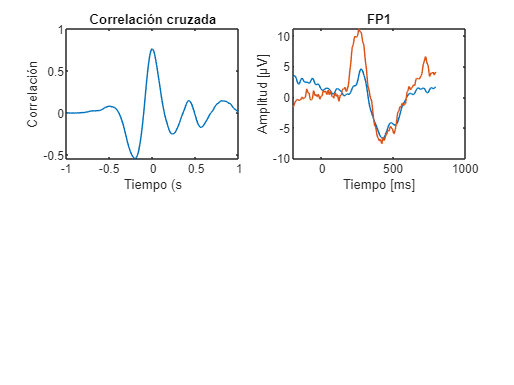

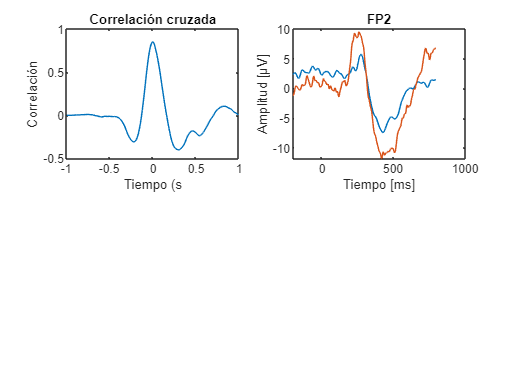

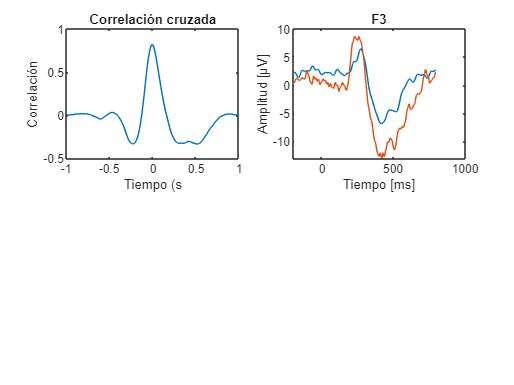

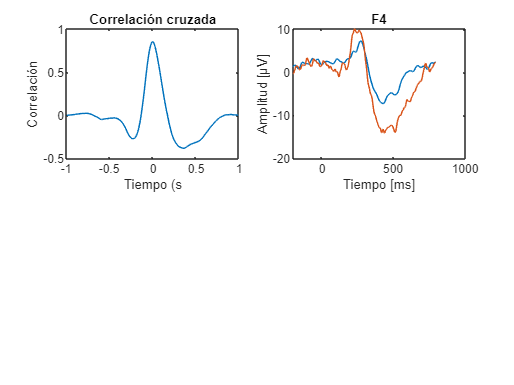

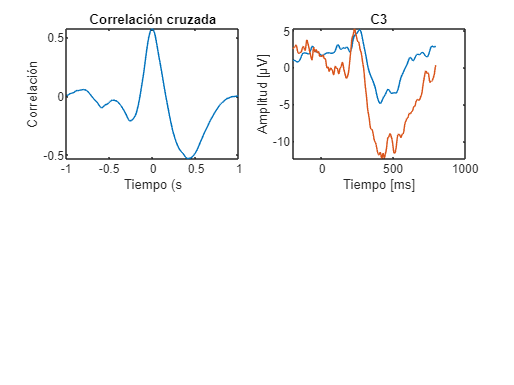

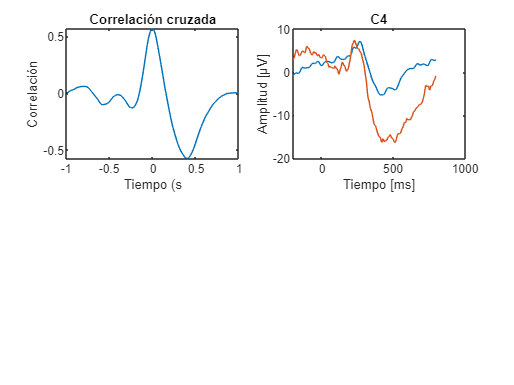

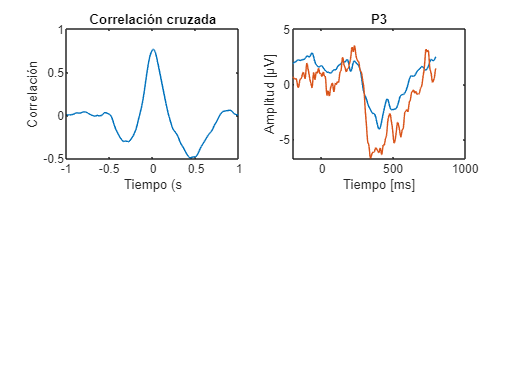

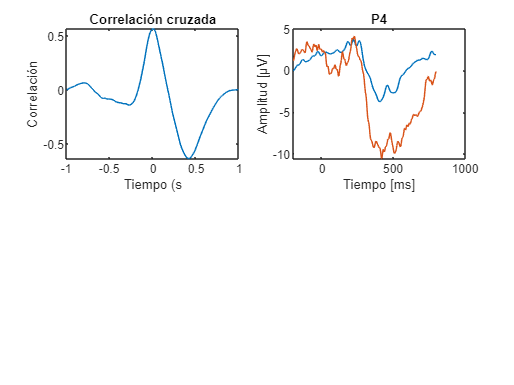

    for j=1:22
    figure
    
  subplot(2,2,1)
    plot(lags(j,:)/EEG.srate,rxx(j,:));
    ylabel('Correlation')
    xlabel('Time (s')
    title('Cross-Correlation') 
   
      subplot(2,2,2)
  plot(EEG.times,RPF(j,:))
    hold on
    plot(EEG.times,RPI(j,:))
    hold off

   title(EEG.chanlocs(j).labels);
   ylabel("Amplitude [μV]")
   xlabel("Time [ms]")
   hold off   

end 